# Los Polinomios Interpolantes

### 15/09/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre las interpolaciones polinomiales*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

`Hola muchachos, esperaba que me recordarán para realizar este documento, pero estoy seguro que todos hemos estado con todos los trabajos y en general con la vida ocupada, no se preocupen. Me acordé de este repaso que les había comentado en la mañana, espero lo puedan aprovechar. Quiero resaltar, haré uso de algunas funciones que no son tan importantes en el curso con el fin de explicar bien a lo que me refiero en cada analisis.`

### Los Polinomios Interpolantes

Este tema es bastante interesante, y además de dar herramientas para aproximar funciones y datos a partir del uso de polinomios, tambien nos dá una intuición sobre el uso de interpolantes, aproximación y funciones especiales mátematicas que posiblemente nos enfrentemos en el mundo diario.

*Este quiza no es un tema tan aplicado y famoso como la solución de ecuaciones diferenciales, pero si es un tema que a gran escala es usado y es base de incluso modelos de clasificación, e inicios de Machine Learning y IA.*

#### Polinomios de Lagrange

Los polinomios de Lagrage siguen un formato básico, exploremoslo un poco:


$$P\left(x\right)=\sum_i \;y_i \;L_i \left(x\right)\;=y_0 \;L_0 \left(x\right)+y_1 \;L_1 \left(x\right)+y_2 \;L_2 \left(x\right)+y_3 \;L_3 \left(x\right)+\;\ldotp \ldotp \ldotp$$


Veamos que estos polinomios siguen un patrón, y es la condición de los polinomios $L_i \left(x=x_i \right)=\delta_{i,j} ,\;\forall x_j \;\not= x_i$, o sea los polinomios son ceros para el resto de nodos empleados menos el nodo correspondiente al valor $y_i$ que se tiene, veamos que esto es lógico, ya que así:


$$P\left(x=x_i \right)=y_i$$


Y las pequeñas fluctuaciones que se obtienen para cumplir este objetivo son ya errores de aproximación que estamos dispuesto a comenter. Veamos un ejemplo usando una función interesante:


$$f\left(x\right)=e^{-x^2 }$$


% Primero hallemos nodos equiespaciados y distribuimos en un rango de
% interes, para este caso usaremos I = [-5, 5]
clear
syms f(x)

f(x) = exp(-x^2);
f = matlabFunction(f);

I = [-5, 5];
X = linspace(I(1), I(2), 11)

X =     -5    -4    -3    -2    -1     0     1     2     3     4     5


Y = f(X);

% Hagamos uso del método
[P, L] = lagran(X, Y)

P =    -0.0000   -0.0000    0.0016   -0.0000   -0.0308    0.0000    0.2519   -0.0000   -0.8548   -0.0000    1.0000


L =     0.0000   -0.0000   -0.0000    0.0000    0.0001   -0.0004   -0.0002    0.0011    0.0002   -0.0008         0
   -0.0000    0.0000    0.0001   -0.0004   -0.0011    0.0044    0.0035   -0.0139   -0.0025    0.0099         0
    0.0000   -0.0000   -0.0006    0.0017    0.0076   -0.0227   -0.0268    0.0805    0.0198   -0.0595         0
   -0.0000    0.0001    0.0017   -0.0034   -0.0271    0.0542    0.1445   -0.2890   -0.1190    0.2381         0
    0.0001   -0.0001   -0.0031    0.0031    0.0561   -0.0561   -0.3863    0.3863    0.8333   -0.8333         0
   -0.0001   -0.0000    0.0038   -0.0000   -0.0710    0.0000    0.5309   -0.0000   -1.4636   -0.0000    1.0000
    0.0001    0.0001   -0.0031   -0.0031    0.0561    0.0561   -0.3863   -0.3863    0.8333    0.8333         0
   -0.0000   -0.0001    0.0017    0.0034   -0.0271   -0.0542    0.1445    0.2890   -0.1190   -0.2381         0
    0.0000    0.0000   -0.0006   -0.0017    0.0076    0.0227   -0.0268   -0.0805    0.0198    0.0595        

Demosle un poco de significado a cada cosa que tenemos de salida, P corresponde al polinomio interpolante de Lagrange, y L es la matriz de polinomios, donde cada fila corresponde a un polinomio de cada nodo, así:

polynomial = array2table(L);
polynomial.Properties.VariableNames = ["x^10", "x^9", "x^8", "x^7", "x^6", "x^5", "x^4", "x^3", "x^2", "x^1", "x^0"];
polynomial.Properties.RowNames = ["L : x = -5", "L : x = -4", "L : x = -3", "L : x = -2", "L : x = -1", ...
                                       "L : x = 0", "L : x = 1", "L : x = 2", "L : x = 3", "L : x = 4", "L : x = 5"];
disp(polynomial)

                     x^10            x^9            x^8            x^7           x^6            x^5            x^4            x^3           x^2            x^1        x^0
                  ___________    ___________    ___________    ___________    __________    ___________    ___________    ___________    __________    ___________    ___

    L : x = -5     2.7557e-07    -1.3779e-06    -8.2672e-06     4.1336e-05    7.5231e-05    -0.00037616    -0.00022597      0.0011299    0.00015873    -0.00079365     0 
    L : x = -4    -2.7557e-06     1.1023e-05     0.00010747    -0.00042989    -0.

Por ejemplo, veamos el polinomio de $x=0$, en este lo que vamos a ver, es un polinomio donde $x_i \;\not= \;0:L_0 \left(x_i \right)=0$:

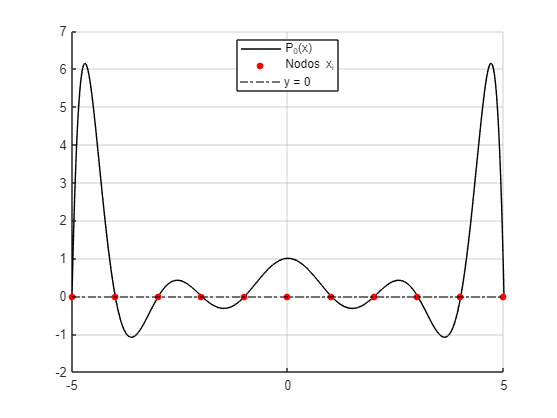

coeficients = L(6, :);
poly0 = @(x) polyval(coeficients, x);

clf('reset')
hold on
fplot(poly0, I, 'k', 'DisplayName', 'P_0(x)')
plot(X, zeros(size(X)),'.r', 'DisplayName', 'Nodos x_i', 'MarkerSize', 15)
yline(0,'-.k', 'DisplayName', 'y = 0')
legend('Location', 'best')
grid on
hold off

Esta es la gráfica asociada al polinomio $L_0 \left(x\right)$, los puntos de interes son los nodos, y veamos que en los nodos distintos a $x=0$ tenemos que la función se anula. Ahora para conocer la función entera, tenemos 2 alternativas, plantear la combinación lineal o usar los coeficientes que ya están cálculados grácias al método.

polynomial = @(x) polyval(P, x);

digits(4)
polynomialSym = vpa(poly2sym(P, x))

$$polynomialSym = -2.807e-5\,x^{10}-2.019e-19\,x^{9}+0.001582\,x^{8}-1.254e-17\,x^{7}-0.03077\,x^{6}+1.075e-16\,x^{5}+0.2519\,x^{4}-2.775e-17\,x^{3}-0.8548\,x^{2}-1.928e-16\,x+1.0$$

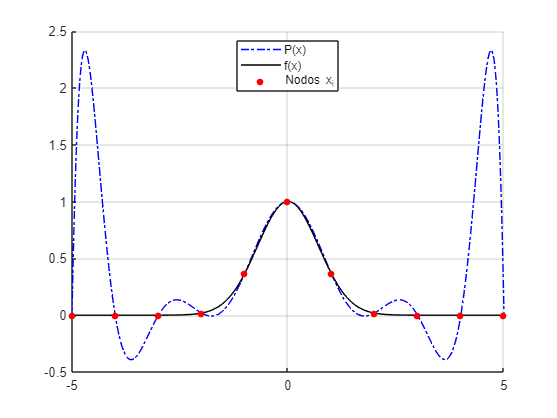

clf('reset')
hold on
fplot(polynomial, I, '-.b', 'DisplayName', 'P(x)')
fplot(f, I, 'k', 'DisplayName', 'f(x)')
plot(X, Y,'.r', 'DisplayName', 'Nodos x_i', 'MarkerSize', 15)
legend('Location', 'best')
grid on
hold off

Y este polinomio es único, claro podemos mejorar la aproximación si en otro caso usaramos más nodos u optaramos por usar los **nodos de Chebyshev**

help cheby

  Entrada   - fun es la funcion introducida con @
            - N es el grado del polinomial interpolante de Chebyshev
            - a es el extremo izquierdo
            - b es el extremo derecho
  Salida    - C es la lista de coeficientes para el polinomio
            - X contiene las abscisas
            - Y contiene las ordenadas



[~, X] = cheby(f, 11, I(1), I(2));
Y = f(X)

Y =     0.0000    0.0000    0.0000    0.0001    0.0257    0.6532    0.6532    0.0257    0.0001    0.0000    0.0000    0.0000


% Hagamos uso del método
[P, L] = lagran(X, Y);
polynomial = @(x) polyval(P, x);
polynomialSym = vpa(poly2sym(P, x))

$$polynomialSym = 5.356e-21\,x^{11}-2.638e-6\,x^{10}-2.937e-19\,x^{9}+0.0001978\,x^{8}+1.14e-17\,x^{7}-0.005553\,x^{6}-1.033e-17\,x^{5}+0.07166\,x^{4}+9.002e-16\,x^{3}-0.4131\,x^{2}-1.314e-15\,x+0.8166$$

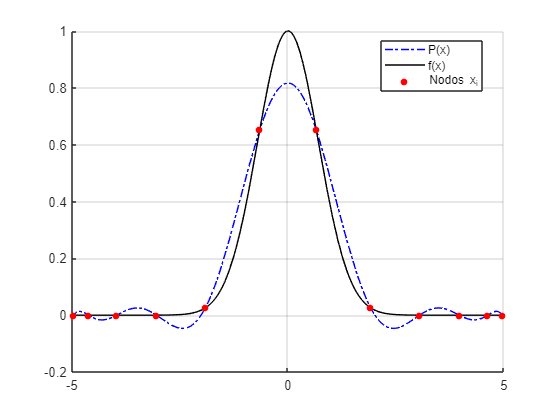

clf('reset')
hold on
fplot(polynomial, I, '-.b', 'DisplayName', 'P(x)')
fplot(f, I, 'k', 'DisplayName', 'f(x)')
plot(X, Y,'.r', 'DisplayName', 'Nodos x_i', 'MarkerSize', 15)
legend('Location', 'best')
grid on
hold off

#### Polinomios de Newton

Los polinomios de Newton siguen una idea similar, exploremoslos un poco usando el anterior ejemplo, no desarrollaremos los gráficos ya que el polinomio es único, por lo cual ambos métodos convergen al mismo polinomio:

% Primero hallemos nodos equiespaciados y distribuimos en un rango de
% interes, para este caso usaremos I = [-5, 5]
clear
syms f(x)

f(x) = exp(-x^2);
f = matlabFunction(f);

I = [-5, 5];
X = linspace(I(1), I(2), 11);
Y = f(X);

% Hagamos uso del método
[P, D] = newpoly(X, Y)

P =    -0.0000         0    0.0016    0.0000   -0.0308    0.0000    0.2519   -0.0000   -0.8548   -0.0000    1.0000


D =     0.0000         0         0         0         0         0         0         0         0         0         0
    0.0000    0.0000         0         0         0         0         0         0         0         0         0
    0.0001    0.0001    0.0001         0         0         0         0         0         0         0         0
    0.0183    0.0182    0.0090    0.0030         0         0         0         0         0         0         0
    0.3679    0.3496    0.1657    0.0522    0.0123         0         0         0         0         0         0
    1.0000    0.6321    0.1413   -0.0081   -0.0151   -0.0055         0         0         0         0         0
    0.3679   -0.6321   -0.6321   -0.2578   -0.0624   -0.0095   -0.0007         0         0         0         0
    0.0183   -0.3496    0.1413    0.2578    0.1289    0.0383    0.0080    0.0012         0         0         0
    0.0001   -0.0182    0.1657    0.0081   -0.0624   -0.0383   -0.0128   -0.0030   -0.0005         0        

Lo interesante de este método es que obtenemos igualmente la tabla de diferencias divididas, está como es impresa hace referencia a esta tabla:

polynomial = array2table(D);
polynomial.Properties.VariableNames = ["Y", "df1", "df2", "df3", "df4", "df5", "df6", "df7", "df8", "df9", "df10"];
polynomial.Properties.RowNames = ["x = -5", "x = -4", "x = -3", "x = -2", "x = -1", "x = 0", "x = 1", "x = 2", " x = 3", ...
                                                                                                           "x = 4", "x = 5"];
disp(polynomial)

                  Y             df1           df2           df3           df4          df5            df6           df7            df8            df9           df10    
              __________    ___________    __________    __________    _________    __________    ___________    __________    ___________    ___________    ___________

    x = -5    1.3888e-11              0             0             0            0             0              0             0              0              0              0
    x = -4    1.1254e-07     1.1252e-07             0             0            0    

El comportamiento es un poco más complejo, pero Newton presenta un polinomio un poco intuitivo a comparación de Lagrange, y el que permite poder definir un nuevo polinomio agregando nuevos nodos si necesidad de un recálculo:


$$P\left(x\right)=\sum_i a_i \;\prod_{i-1} \;\left(x-x_i \right)=a_0 +a_1 \;\left(x-x_0 \right)+a_2 \;\left(x-x_0 \right)\;\left(x-x_1 \right)+\;\ldotp \ldotp \ldotp$$


Demostrar la propiedad que comentabamos anteriormente no es dificil, veamos que:


$$P_n \left(x\right)=\;$$

$$a_0 +a_1 \;\left(x-x_0 \right)+a_2 \;\left(x-x_0 \right)\;\left(x-x_1 \right)+\;\ldotp \ldotp \ldotp +\;a_n \;\left(x-x_0 \right)\;\ldotp \ldotp \ldotp \left(x-x_{n-1} \right)$$



$$P_{n+1} \left(x\right)=\;$$

$$a_0 +a_1 \;\left(x-x_0 \right)\;\;+\;\ldotp \ldotp \ldotp +\;a_n \;\left(x-x_0 \right)\;\ldotp \ldotp \ldotp \left(x-x_{n-1} \right)+\;a_{n+1} \;\left(x-x_0 \right)\;\ldotp \ldotp \ldotp \left(x-x_n \right)$$



$$P_{n+1} \left(x\right)=P_n \left(x\right)+\;a_{n+1} \;\left(x-x_0 \right)\;\ldotp \ldotp \ldotp \left(x-x_n \right)$$


Y esta propiedad no la teniamos con el polinomio interpolante de** Lagrange, **Ahora exploremos un poco de la tabla de diferencias divididas, veamos que iterativamente definimos cada termino de la diagonal inferior como:

`D(i, j) = ( D(i, j-1) - D(i-1, j-1) ) / ( X(i) - X(i-j + 1) ) : i >= j`

O sea veamos que cada elemento lo podemos definir como:

% Comparemos los valores de la tabla de diferencias divididas, y el
% algoritmo propuesto
Dij = D(7, 6)

Dij = -0.0095

i = 7; j = 6;

Dexpected = ( D(i, j-1) - D(i-1, j-1) ) / ( X(i) - X(i-j + 1) )

Dexpected = -0.0095

Dij == Dexpected

ans = logical
   1


*Veamos que si se cumple.*

Veamos de igual forma que se trata del mismo polinomio que encontramos anteriormente:

polynomial = @(x) polyval(P, x);
polynomialSym = vpa(poly2sym(P, x))

$$polynomialSym = -2.807e-5\,x^{10}+0.001582\,x^{8}+8.674e-19\,x^{7}-0.03077\,x^{6}+1.388e-17\,x^{5}+0.2519\,x^{4}-2.498e-16\,x^{3}-0.8548\,x^{2}-5.551e-17\,x+1.0$$

clf('reset')
hold on
fplot(polynomial, I, '-.b', 'DisplayName', 'P(x)')
fplot(f, I, 'k', 'DisplayName', 'f(x)')
plot(X, Y,'.r', 'DisplayName', 'Nodos x_i', 'MarkerSize', 15)
legend('Location', 'best')
grid on
hold off

digits(32)
clear